# **TRABAJO CONVOCATORIA EXTRAORDINARIA**

### **POR: ALFONSO GIL GIRÓN Y EDUARDO PÉREZ MUÑOZ DE LUNA**

Para el archivo de datos dado, seleccione todos los vuelos que llegan a un aeropuerto dado. (Por ejemplo, los vuelos que llegan a San Diego (SAN)). Este va a ser su conjunto de datos población).

clear all
clc
% Cargamos los datos
flights = importFlightsData("flightsNov.csv");

head(flights)

ans = 8×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    _______________

summary(flights)

Variables:

    AIRLINE: 467972×1 categorical

        Values:

            American Airlines                   73871
            Alaska Airlines                     13950
            JetBlue Airways                     21697
            Delta Airlines                      72228
            Atlantic Southeast Airlines         42572
            Frontier Airlines                    7763
            Hawaiian Airlines                    6024
            American Eagle Airlines             20305
            Spirit Airlines                     10164
            Skywest Airlines                    47292
            United Airlines                     42647
            Virgin America                       5414
            Southwest Airlines             1.0405e+05
            US Airways                              0

    TAIL_NUMBER: 467972×1 categorical

        Values:

            7819A           167   
            N001AA           32   
            N002AA 


cond1=find(flights.DESTINATION=="SAN");
Arr3 = flights(cond1,:);
cond2 = isnan(Arr3.ACTUAL_ELAPSED_TIME)

cond2 = 5965×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


Datos = Arr3(cond2==0,:);

El conjunto de datos con el que vamos a trabajar es 'Datos' que son todos los vuelos que llegan a SAN.

**Pinte en un histograma la duración real del vuelo, calcule la media, varianza, mediana, etc.**

**Ajústela a un modelo de probabilidad.**

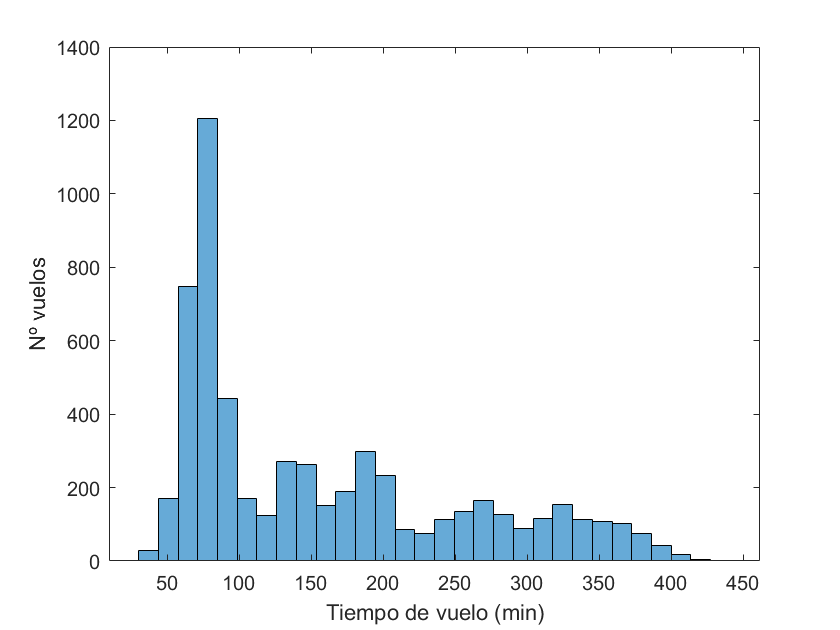

histogram(Datos.ACTUAL_ELAPSED_TIME,30)
xlabel('Tiempo de vuelo (min)')
ylabel('Nº vuelos')


media = mean(Datos.ACTUAL_ELAPSED_TIME)

media = 157.7858

varianza = var(Datos.ACTUAL_ELAPSED_TIME)

varianza = 9.4856e+03

mediana = median(Datos.ACTUAL_ELAPSED_TIME)

mediana = 127

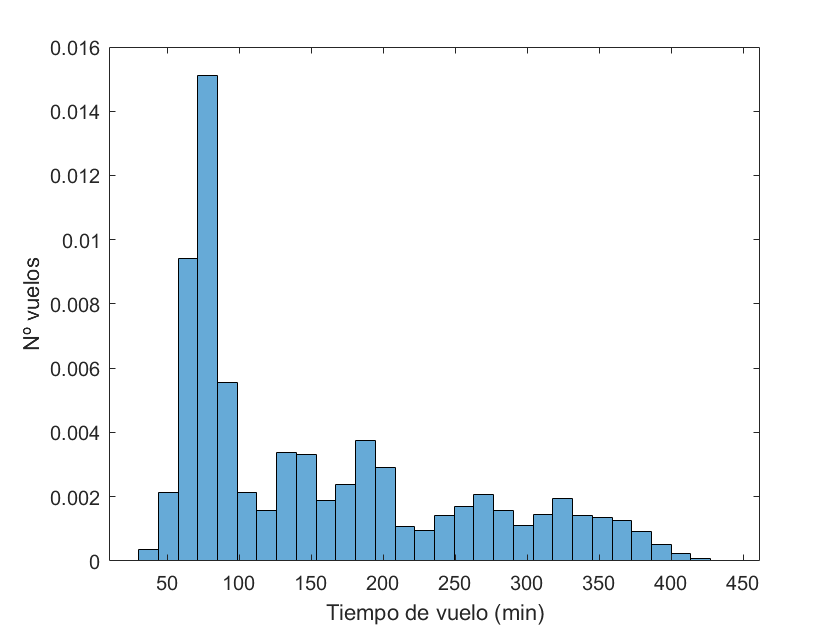


% Histograma Normalizado
histogram(Datos.ACTUAL_ELAPSED_TIME,30,"Normalization","pdf")
xlabel('Tiempo de vuelo (min)')
ylabel('Nº vuelos')

**Calcule la diferencia entre el tiempo programado y el tiempo que realmente tarda. Dibuje esta nueva variable en un histograma y ajústela a un modelo de probabilidad. Calcule la media, varianza, mediana, moda…**

% Duration Diff

Duration_diff = Arr3.ACTUAL_ELAPSED_TIME-Arr3.SCHEDULED_ELAPSED_TIME;

cond3 = isnan(Duration_diff)

cond3 = 5965×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


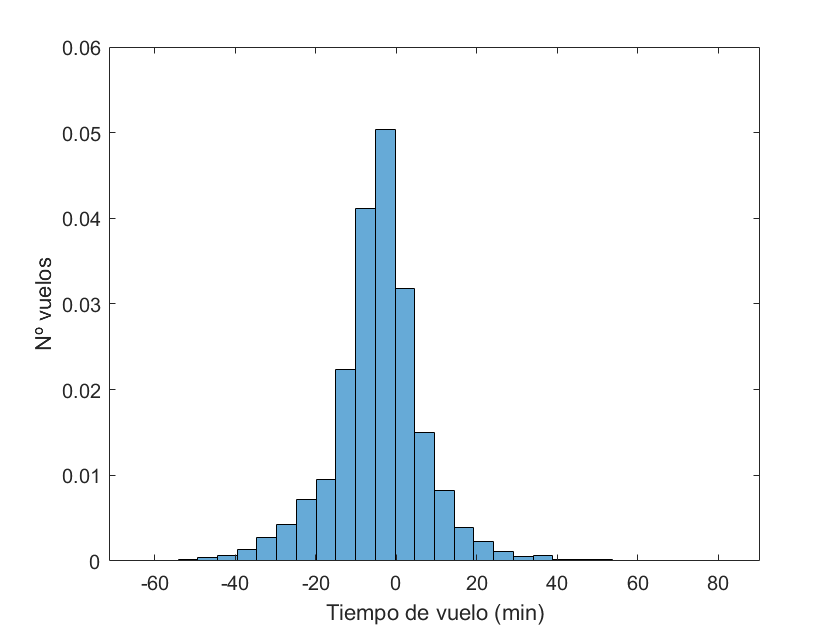

Datos2 = Duration_diff(cond3==0,:);

histogram(Datos2,30,"Normalization","pdf")
xlabel('Tiempo de vuelo (min)')
ylabel('Nº vuelos')


media_diff=mean(Datos2)

media_diff = -4.4671

varianza_diff = var(Datos2)

varianza_diff = 134.6148

mediana_diff = median(Datos2)

mediana_diff = -4

moda_diff = mode(Datos2)

moda_diff = -5

**Seleccione los vuelos que llegan desde una ciudad determinada (por ejemplo NY o SF). Para todos esos vuelos, represente un histograma con el tiempo que tardan, y ajústelo a un modelo de probabilidad.Calcule el tiempo medio que tardan. Obtenga una tabla con dichos vuelos agrupados por compañías aéreas.**

% implementamos la condicion para los vuelos que llegan desde Nueva York
cond4 = find(Arr3.ORIGIN=="JFK");
Arr4 = Arr3(cond4,:);
%implementamos la condición para quitar todos los valores Nan
cond5 = isnan(Arr4.ACTUAL_ELAPSED_TIME)

cond5 = 164×1 logical array
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0


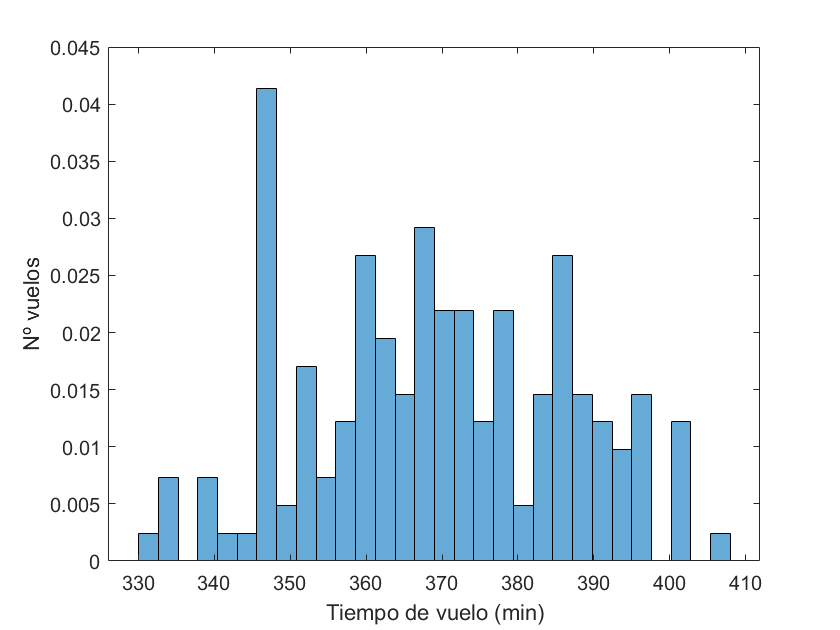

Datos3 = Arr4(cond5==0,:);

histogram(Datos3.ACTUAL_ELAPSED_TIME,30,"Normalization","pdf")
xlabel('Tiempo de vuelo (min)')
ylabel('Nº vuelos')


media_NY = mean(Datos3.ACTUAL_ELAPSED_TIME)

media_NY = 369.1456

%tabal de todas las compañías aereas agrupadas
ArrCompany = groupsummary(Arr4,"AIRLINE");
sortrows(ArrCompany, "GroupCount","descend")

ans = 3×2 table
         AIRLINE         GroupCount
    _________________    __________

    Delta Airlines           75    
    JetBlue Airways          55    
    American Airlines        34    



sortrows(Datos3, "AIRLINE","descend")

ans = 158×20 table
       AIRLINE        TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    ______________    ___________    _____________    ______    ___________    ________________________    _____________________    _______________ 

**De la tabla anterior, selecciona la segunda y tercera compañía más vuelos, y haz un contraste comparando sus medias. Por otro lado, selecciona la compañía con más vuelos. Calcula el tiempo medio que tardan los aviones. Haz un contraste comparando dicha media con la media calculada para todas las compañías.**

%ponemos la condición para solo los de la compañia indicada
cond6 = find(Datos3.AIRLINE=="JetBlue Airways");
cond7 = find(Datos3.AIRLINE=="American Airlines");

Jetblue = Datos3(cond6,:);
American = Datos3(cond7,:);

media_jet=mean(Jetblue.ACTUAL_ELAPSED_TIME)

media_jet = 368.7170

media_american=mean(American.ACTUAL_ELAPSED_TIME)

media_american = 367.9063

%contraste de las medias 
[h,p] = ttest2(media_jet,media_american)

h = NaN

p = NaN

%ponemos la condición para solo los de la compañia indicada
cond8 = find(Datos3.AIRLINE=="Delta Airlines");
Delta = Datos3(cond8,:);
media_delta= mean(Delta.ACTUAL_ELAPSED_TIME)

media_delta = 370

%contraste de las medias
[h,p] = ttest2(media_delta,media_NY)

h = NaN

p = NaN

**Propón otros 2 contrastes parecidos al anterior, y calcula la probabilidad de cometer error tipo I y error tipo II.**

En el primer ejemplo hemos seleccionado un contraste de hipotesis en la cual la media de la compañía American Airlines es igual a la media total de todos los vuelos que vienen de Nueva York. La cual sería un contraste de hipótesis por Simulaciones de Monte Carlo de 2 colas, en la cual calculamos tanto el contraste como los Errores Tipo I y II. 

%desviaciones típicas
des_jet=std(Jetblue.ACTUAL_ELAPSED_TIME)

des_jet = 16.9415

des_american=std(American.ACTUAL_ELAPSED_TIME)

des_american = 16.7878

des_delta=std(Delta.ACTUAL_ELAPSED_TIME)

des_delta = 17.8528

des_NY=std(Datos3.ACTUAL_ELAPSED_TIME)

des_NY = 17.2508


%errores y tests
%AMERICAN-TODOS
%media american=media de todos
% Datos poblacionales
mu_0 = media_american;
sigma0 =des_american;

% Muestra
Xbar = media_NY; % Media muestral
N = 100;
sigma_bar = sigma0/sqrt(N) % Teorema varianza de la media simple

sigma_bar = 1.6788

Tobs = (Xbar - mu_0)/sigma_bar; % Normalización de la muestra

% Modelo para la simulación MC
M = 1000; % Nº experimentos Monte Carlo
Tm = zeros(1,M); % Resultados
rng('default') % Semilla

for i =1:M
   Xm = sigma0*randn(N,1) + mu_0; % Creamos muestras de la población
   Tm(i) = (mean(Xm) - mu_0)/sigma_bar; % Normalización
end

alpha = 0.05;
VCHi_mc = quantile(Tm,1-alpha) % Cuantil 9.95

VCHi_mc = 1.5177

VCLo_mc = quantile(Tm,alpha) % Cuantil 0.05

VCLo_mc = -1.5033

VC_teo = norminv(1-alpha)

VC_teo = 1.6449

x = norminv(1-alpha,mu_0)

x = 369.5511


disp('Si Tobs > Valor crítico obtenido por MC, rechazamos H0')

Si Tobs > Valor crítico obtenido por MC, rechazamos H0


sprintf('Tobs = %0.5f',Tobs)

ans = 'Tobs = 0.73823'

sprintf('T_c_MC = %0.5f',VCLo_mc)

ans = 'T_c_MC = -1.50330'

if(Tobs>VCLo_mc)
    disp('Se rechaza la hipótesis')
else 
    disp('No se rechaza la hipótesis')
end

Se rechaza la hipótesis


%ERROR 2
% Datos poblacionales
mu_0 = media_american;
sigma0 =des_american;

% Muestra
Xbar = media_NY; % Media muestral
N = 100;
sigma_bar = sigma0/sqrt(N) % Teorema varianza de la media simple

sigma_bar = 1.6788

Tobs = (Xbar - mu_0)/sigma_bar; % Normalización de la muestra

%Simulación MC bajo H0 
rng('default') %semilla
M = 5000; %n experimentos

for i =1:M
   Xm = sigma0*randn(N,1) + mu_0;
   Tm(i) = (mean(Xm) - mu_0)/sigma_bar; %5000 estadisticos de muestras de la población
end

alpha = 0.05;
VC_hi = quantile(Tm,1-alpha) % 95%

VC_hi = 1.6415

VC_lo = quantile(Tm,alpha) % 5%

VC_lo = -1.6085

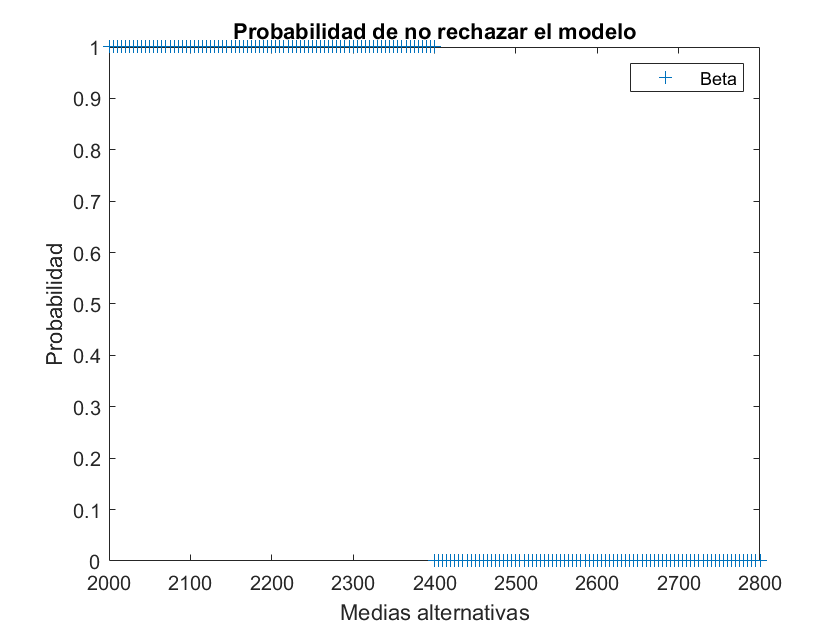


%Simulación MC bajo H1
M = 5000; %nº experimentos

%medias alternativas
%Cola superior
mualt1 = 2400:5:2800;
%Cola inferior
mualt2 = 2000:5:2400;

%beta1
betahat1 = zeros(size(mualt1));
for j =1:length(mualt1);
   Tm = zeros(1,M);
   for i =1:M
       xs = sigma0*randn(N,1) + mualt1(j);
       Tm(i) = (mean(xs) - mu_0)/sigma_bar;
   end
   Tm_s =Tm;
   betahat1(j) = sum(Tm_s < VC_hi)/M; % no se rechaza H0
end

%beta2
betahat2 = zeros(size(mualt2));
for j =1:length(mualt2);
   Tm = zeros(1,M);
   for i =1:M
       xs = sigma0*randn(N,1) + mualt2(j);
       Tm(i) = (mean(xs) - mu_0)/sigma_bar;
   end
   Tm_s =sort(Tm);
   betahat2(j) = sum(Tm_s > VC_lo)/M; %no se rechaza H0
end
%ERROR TIPO I
%beta1
betahat12 = zeros(size(mualt1));
for j =1:length(mualt1);
   Tm2 = zeros(1,M);
   for i =1:M
       xs2 = sigma0*randn(N,1) + mualt1(j);
       Tm2(i) = (mean(xs2) - mu_0)/sigma_bar;
   end
   Tm_s2 =sort(Tm2);
   betahat12(j) = sum(Tm_s2 > VC_hi)/M; % no se rechaza H0
end

%beta2
betahat22 = zeros(size(mualt2));
for j =1:length(mualt2);
   Tm2 = zeros(1,M);
   for i =1:M
       xs2 = sigma0*randn(N,1) + mualt2(j);
       Tm2(i) = (mean(xs2) - mu_0)/sigma_bar;
   end
   Tm_s2 =sort(Tm2);
   betahat22(j) = sum(Tm_s2 < VC_lo)/M; %no se rechaza H0
end

plot ([mualt1,mualt2],[betahat1,betahat2],'+')
hold on
axis tight
legend('Beta')
title('Probabilidad de no rechazar el modelo')
xlabel('Medias alternativas')
ylabel('Probabilidad')
hold off

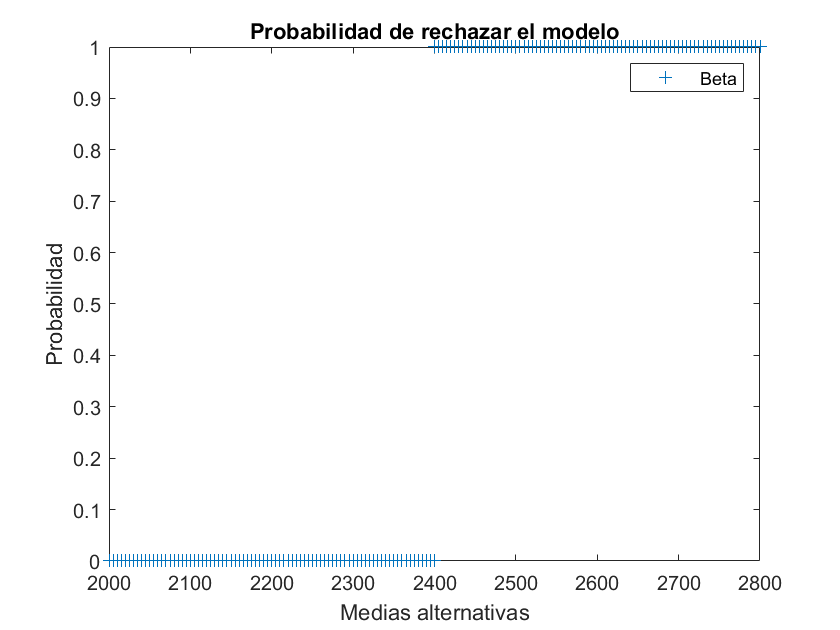


plot ([mualt1,mualt2],[betahat12,betahat22],'+')
hold on
axis tight
legend('Beta')
title('Probabilidad de rechazar el modelo')
xlabel('Medias alternativas')
ylabel('Probabilidad')
hold off

En el segundo contraste lo que vamos a tener como hipotesis nula es que la media de American Airlines es mayor, es decir que el tiempo de vuelo medio es mayor. Por tanto realizamos un contraste de hipotesis por Simulaciones Monte Carlo de 1 cola.

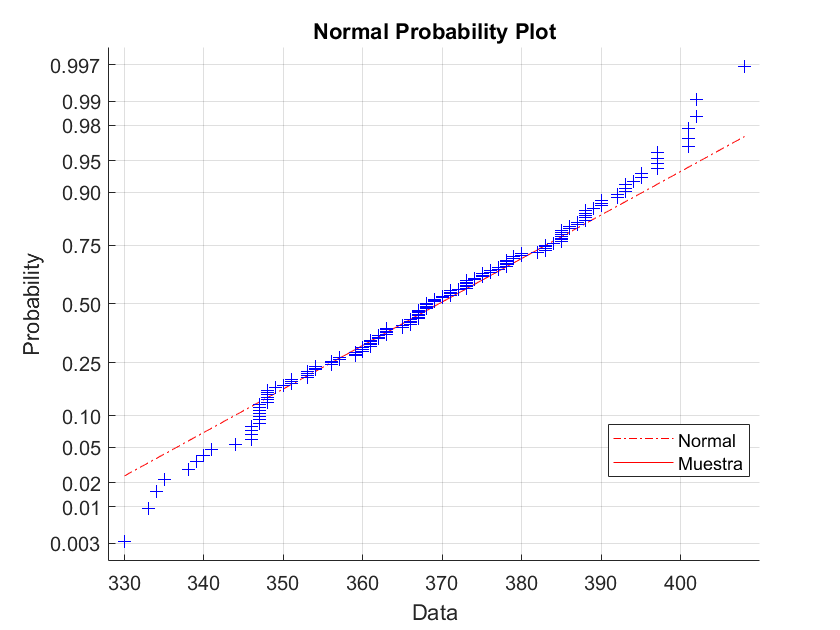

% La media, la desviación típica del enunciado y la longitud de la muestra
sigma=des_american; 
mu=media_american;
N=length(Datos3.ACTUAL_ELAPSED_TIME);

% Definimos el estadístico y calculamos su z (To)
mediamuestral =media_NY;
sigma_bar = sigma/sqrt(N);
To= (mediamuestral - mu)/sigma_bar;
normplot(Datos3.ACTUAL_ELAPSED_TIME)
legend('Normal', 'Muestra','Location',"best")

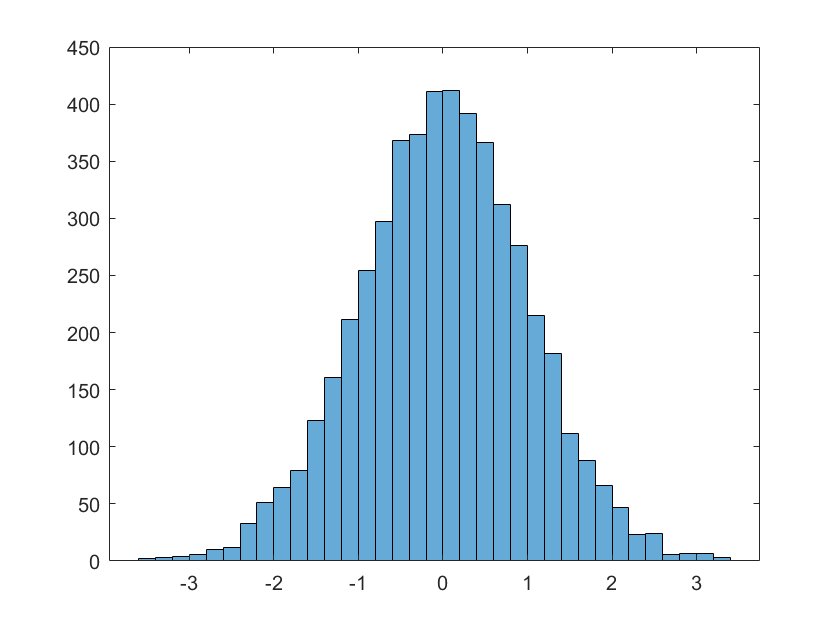


% Simulamos una normal 
Tm= zeros(1,M); 
rng('default')
for i= 1:M
    Xm= sigma*randn(1,N) + mu;
    Tm(i) = (mean(Xm) - mu)/ sigma_bar;
end
histogram(Tm)


%Comprobamos la hipótesis comparando la z del estadístico con la del
%intervalo
alpha= 0.05;
VC_mc= quantile(Tm, 1-alpha);
if (To>VC_mc)
    disp('Se rechaza H0')
else
    disp('No se rechaza H0')
end   

No se rechaza H0



n=length(Datos3.ACTUAL_ELAPSED_TIME);
mu0= media_american; 
mediamuestral = media_NY; 
sigma=des_american;

% Simulación Monte Carlo con una normal
M=1000;
Im= 0; 
rng('default')
for k = 1:M
    % Random Sample under H_0
    xs= sigma*randn(1,n) + mu0;
    Tm= mean(xs);
    if Tm>= mediamuestral 
        Im= Im+1;
    end
end
Laplace= Im/M

Laplace = 0.1760

sprintf('Probabilidad = %0.2f%%', Laplace*100)

ans = 'Probabilidad = 17.60%'

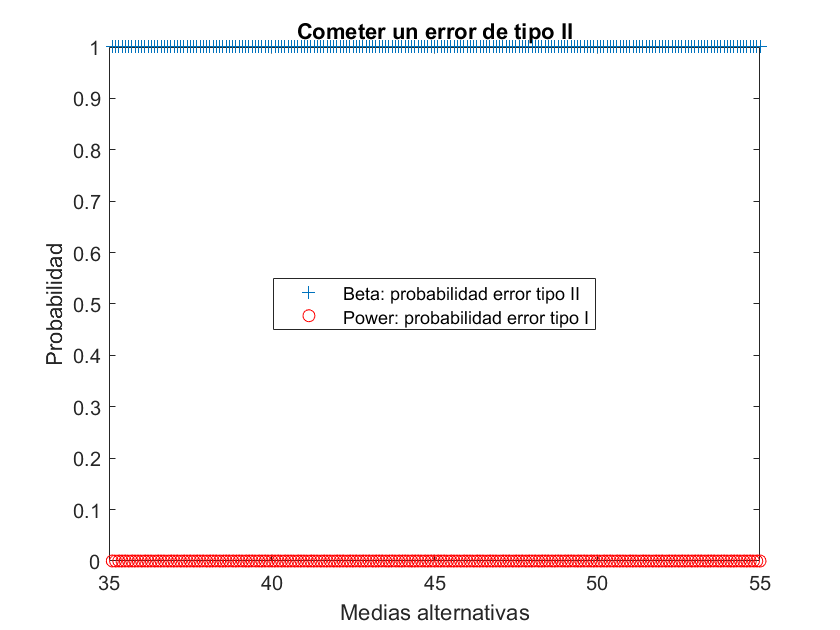

%Error tipo I-II

N = length(Datos3.ACTUAL_ELAPSED_TIME);

% Datos poblacionales
sigma = des_american; 
mu_0 = media_american;

%Calculamos estadístico normalizado
X_bar = mean(Datos3.ACTUAL_ELAPSED_TIME); %media muestral
sigma_bar = sigma/sqrt(N); % varianza de la media simple
Tobs = (X_bar - mu_0)/sigma_bar;

%Simulación MC bajo H1
M = 1000; %nº experimentos
mualt = 35.1:0.1:55; %medias alternativas
betahat = zeros(size(mualt)); %beta

for j = 1:length(mualt) %mil experimentos para cada media alternativa
    Tm = zeros(1,M); %lista de estadísticos 
    for i = 1:M;
        xs = sigma*randn(N,1) + mualt(j); %nueva muestra de poblacion con media mj
        Tm(i) = (mean(xs)-mu_0)/sigma_bar; %añadimos estadístico a la lista 
    end
   
    betahat(j) = sum(Tm<Tobs)/M; %no rechazar
end

plot(mualt,betahat,'+')
hold on
plot(mualt,1-betahat,'or')
title('Cometer un error de tipo II')
legend('Beta: probabilidad error tipo II','Power: probabilidad error tipo I',"Location","best")
xlabel('Medias alternativas')
ylabel('Probabilidad')
hold off

sprintf('Probabilidad de %0.2f%% de cometer un error de tipo II para una media de 45', betahat(find(mualt==45))*100)

ans = 'Probabilidad de 100.00% de cometer un error de tipo II para una media de 45'

**Para todos los vuelos que llegan a la ciudad seleccionada, represente la duración total del vuelo en función de la distancia, en función del tiempo en aire, en función del tiempo de taxi (antes y después del vuelo). Plantee un modelo de regresión lineal multivariable para predecir el tiempo de vuelo en función de la distancia y el tiempo de taxi.**

Realizamos la representación en función que representa la duración total del vuelo en función de la distancia, en función del tiempo en aire y en función del tiempo en taxi.

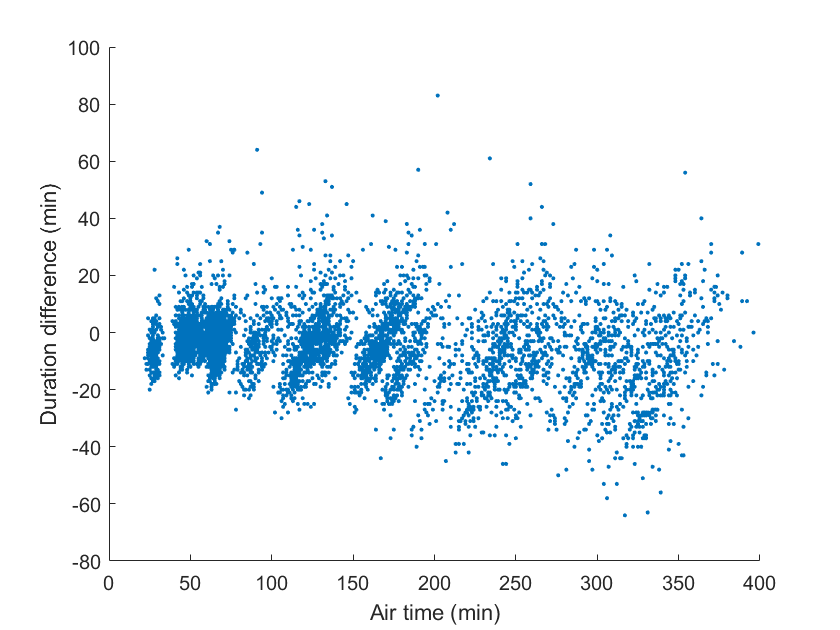

scatter(Datos.AIR_TIME, Datos2,'.')
xlabel('Air time (min)')
ylabel('Duration difference (min)')

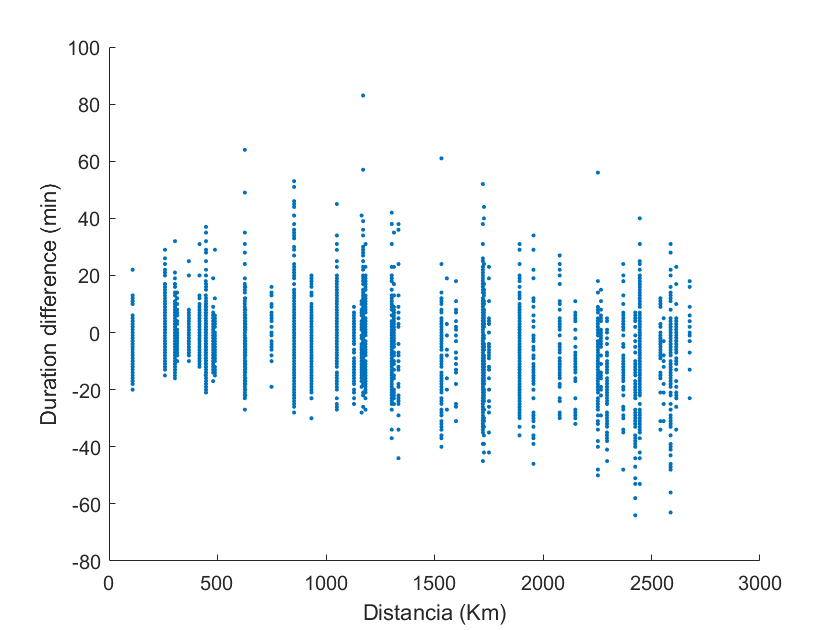


scatter(Datos.DISTANCE, Datos2,'.')
xlabel('Distancia (Km)')
ylabel('Duration difference (min)')

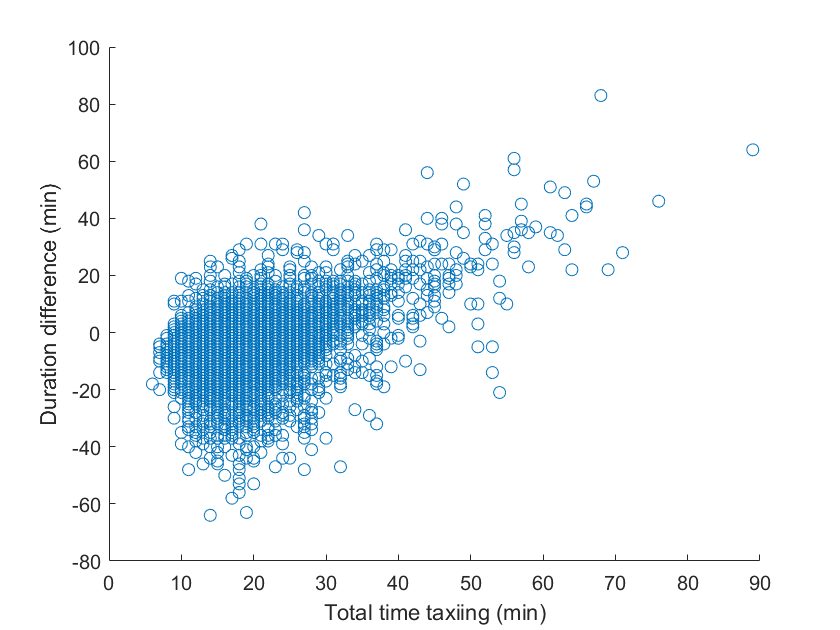


Datos.TAXI_TOTAL = Datos.TAXI_OUT + Datos.TAXI_IN;
scatter(Datos.TAXI_TOTAL, Datos2)
xlabel('Total time taxiing (min)')
ylabel('Duration difference (min)')

Realizamos un modelo de regresión lineal multivariable  para predecir el tiempo en función de la distancia y el tiempo en taxi

 p = polyfit(Datos.DISTANCE,Datos.TAXI_TOTAL,2)

p =     0.0000    0.0017   16.5243


 % p= 0 + 0.0017x +16.5243x^2

He realizado este tipo de modelo de regresión debido a que no conseguía sacarlo mediante otro.